clear
clc
%% Packet Size
% Symbols
Ns = 3e4 ;
% Symbols per packet
Nm = 1e1 ;
N = Ns/Nm ;
%% SF and BW initializing
SF = 7 ;
M = 2^SF ;
Ts = M ;
BW = 125e3 ;
%% Define parameters
t = 0:1/Ts:0.999 ;
tR = kron(ones(1,Ns),t) ;
%% Create random symbols
x = randi(M,1,Ns) - 1 ;
%% Create Chirps
upChirp = loramod(x,SF,BW,BW) ;
dnChirp = loramod(0,SF,BW,BW,-1) ;
signal = upChirp.*repmat(dnChirp,length(upChirp)./length(dnChirp),1) ;
%% Initiate SNR
SNR = -5 : 5;
EbNo = SNR + 10.*log10(M/SF) ;
EsNo = EbNo + 10.*log10(SF) ;
%% Simulation Loop
for CtrSNR = 1 : length(SNR)
    sigma = 1./10.^(SNR(CtrSNR)./20) ;
    h = abs(reshape(1/sqrt(2).*(randn(1,Ns/Nm) + 1i.*randn(1,Ns/Nm)).*ones(M.*Nm,1),M.*Ns,1)) ;
    n = sigma/sqrt(2).*(randn(M.*Ns,1) + 1i.*randn(M.*Ns,1)) ;
    Rx1 = signal + n ;
     Rx2 = h.*signal + n ;
    %% Non-Coherent
    % AWGN
    [~,idx] = max(fft(reshape(Rx1,M,Ns))) ;
    ynCoh1 = idx - 1 ;
    % Rayleigh
    [~,idx] = max(fft(reshape(Rx2,M,Ns))) ;
    ynCoh2 = idx - 1 ;
    %% Coherent
    for CtrM = 1 : M
        % AWGN
        rtemp1 = conv(Rx1,exp(-1i.*2.*pi.*(M - CtrM + 1).*t)) ;
        r1(CtrM,:) = real(rtemp1(Ts+1:Ts:end)) ;
        % Rayleigh
        rtemp2 = conv(Rx2,exp(-1i.*2.*pi.*(M - CtrM + 1).*t)) ;
        r2(CtrM,:) = real(rtemp2(Ts+1:Ts:end)) ;
    end
    [~,idx] = max(r1) ;
    yCoh1 = idx - 1 ;
    [~,idx] = max(r2) ;
    yCoh2 = idx - 1 ;
    %% BER Simulation
    BER_nCOH_AWGN_SIMULATION(CtrSNR) = sum(sum(abs(de2bi(ynCoh1,M) - de2bi(x,M))))/(SF.*Ns) ;
    BER_nCOH_RAY_SIMULATION(CtrSNR)  = sum(sum(abs(de2bi(ynCoh2,M) - de2bi(x,M))))/(SF.*Ns) ;
    BER_COH_AWGN_SIMULATION(CtrSNR)  = sum(sum(abs(de2bi(yCoh1,M) - de2bi(x,M))))/(SF.*Ns) ;
    BER_COH_RAY_SIMULATION(CtrSNR)   = sum(sum(abs(de2bi(yCoh2,M) - de2bi(x,M))))/(SF.*Ns) ;
    %% SER Simulation
    SER_nCOH_AWGN_SIMULATION(CtrSNR) = sum(abs(ynCoh1 - x)>0)/Ns ;
    SER_nCOH_RAY_SIMULATION(CtrSNR)  = sum(abs(ynCoh2 - x)>0)/Ns ;
    SER_COH_AWGN_SIMULATION(CtrSNR)  = sum(abs(yCoh1 - x)>0)/Ns ;
    SER_COH_RAY_SIMULATION(CtrSNR)   = sum(abs(yCoh2 - x)>0)/Ns ;
    %% PER Simulation
    PER_nCOH_AWGN_SIMULATION(CtrSNR) = sum(sum(abs(reshape(x,N,Nm) - reshape(ynCoh1,N,Nm)),2)>0)/N ;
    PER_nCOH_RAY_SIMULATION(CtrSNR)  = sum(sum(abs(reshape(x,N,Nm) - reshape(ynCoh2,N,Nm)),2)>0)/N ;
    PER_COH_AWGN_SIMULATION(CtrSNR)  = sum(sum(abs(reshape(x,N,Nm) - reshape(yCoh1,N,Nm)),2)>0)/N ;
    PER_COH_RAY_SIMULATION(CtrSNR)   = sum(sum(abs(reshape(x,N,Nm) - reshape(yCoh2,N,Nm)),2)>0)/N ;
    %% Loading Display
    CtrSNR
end

CtrSNR = 1

CtrSNR = 2

CtrSNR = 3

CtrSNR = 4

CtrSNR = 5

CtrSNR = 6

CtrSNR = 7

CtrSNR = 8

CtrSNR = 9

CtrSNR = 10

CtrSNR = 11

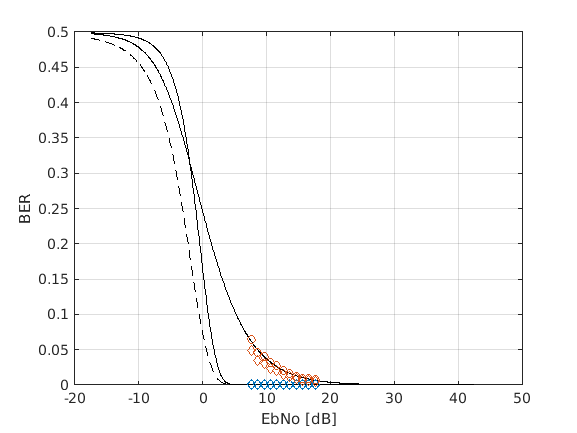

%% Analytic
SNR_theory = linspace(-30,30,1e3) ;
EbNo_theory = SNR_theory + 10.*log10(M/SF) ;
EsNo_theory = EbNo_theory + 10.*log10(SF) ;
% Theoretical BER Calculations
BER_nCOH_AWGN_Theory = 0.5.*qfunc(sqrt(10.^(SNR_theory./10).*2.*M) - sqrt(1.386.*SF+1.154)) ; % T. Elshabrawy and J. Robert, "Closed-Form Approximation of LoRa Modulation BER Performance," in IEEE Communications Letters, vol. 22, no. 9, pp. 1778-1781, Sept. 2018, doi: 10.1109/LCOMM.2018.2849718.
BER_nCOH_RAY_Theory  = berfading(EbNo_theory,'fsk',M,1,'noncoherent') ;
BER_COH_AWGN_Theory  = berawgn(EbNo_theory,'fsk',M,'coherent') ;
% BER_COH_RAY_Theory   = berfading(EbNo_theory,'fsk',M,1,'coherent') ;
% Theoretical SER Calculations
SER_nCOH_AWGN_Theory = (M - 1)./(2.^(SF - 1)).*BER_nCOH_AWGN_Theory ;
% Theoretical SER Calculations
SER_nCOH_AWGN_Theory = (M - 1)./(2.^(SF - 1)).*BER_nCOH_AWGN_Theory ;
SER_nCOH_RAY_Theory  = (M - 1)./(2.^(SF - 1)).*BER_nCOH_RAY_Theory ;
SER_COH_AWGN_Theory  = (M - 1)./(2.^(SF - 1)).*BER_COH_AWGN_Theory ;
% SER_COH_RAY_Theory   = (M - 1)./(2.^(SF - 1)).*BER_COH_RAY_Theory ;
% Theoretical PER Calculations
PER_nCOH_AWGN_Theory = 1 - (1 - SER_nCOH_AWGN_Theory).^Nm ;
PER_nCOH_RAY_Theory  = 1 - (1 - SER_nCOH_RAY_Theory).^Nm ;
PER_COH_AWGN_Theory  = 1 - (1 - SER_COH_AWGN_Theory).^Nm ;
% PER_COH_RAY_Theory   = 1 - (1 - SER_COH_RAY_Theory).^Nm ;
%% Plots
% BER
figure(1)
clf
ax = gca ;
hold on
plot(EbNo_theory,BER_nCOH_AWGN_Theory,'k-')
plot(EbNo_theory,BER_nCOH_RAY_Theory,'k-')
plot(EbNo_theory,BER_COH_AWGN_Theory,'k--')
% plot(EbNo_theory,BER_COH_RAY_Theory,'k--')
plot(EbNo,BER_nCOH_AWGN_SIMULATION,'o','color',ax.ColorOrder(1,:))
plot(EbNo,BER_nCOH_RAY_SIMULATION,'o','color',ax.ColorOrder(2,:))
plot(EbNo,BER_COH_AWGN_SIMULATION,'d','color',ax.ColorOrder(1,:))
plot(EbNo,BER_COH_RAY_SIMULATION,'d','color',ax.ColorOrder(2,:))
xlabel(' EbNo [dB] ')
ylabel(' BER ')
box on
grid on

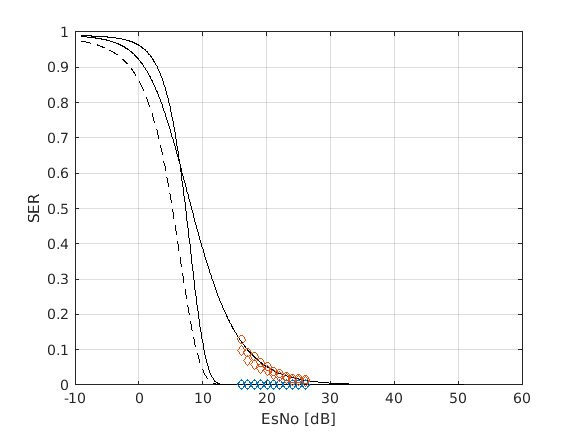

% SER
figure(2)
clf
ax = gca ;
hold on
plot(EsNo_theory,SER_nCOH_AWGN_Theory,'k-')
plot(EsNo_theory,SER_nCOH_RAY_Theory,'k-')
plot(EsNo_theory,SER_COH_AWGN_Theory,'k--')
% plot(EsNo_theory,SER_COH_RAY_Theory,'k--')
plot(EsNo,SER_nCOH_AWGN_SIMULATION,'o','color',ax.ColorOrder(1,:))
plot(EsNo,SER_nCOH_RAY_SIMULATION,'o','color',ax.ColorOrder(2,:))
plot(EsNo,SER_COH_AWGN_SIMULATION,'d','color',ax.ColorOrder(1,:))
plot(EsNo,SER_COH_RAY_SIMULATION,'d','color',ax.ColorOrder(2,:))
xlabel(' EsNo [dB] ')
ylabel(' SER ')
box on
grid on

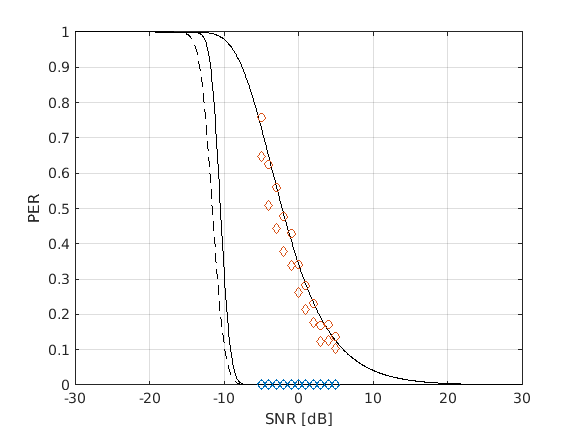

% PER
figure(3)
clf
ax = gca ;
hold on
plot(SNR_theory,PER_nCOH_AWGN_Theory,'k-')
plot(SNR_theory,PER_nCOH_RAY_Theory,'k-')
plot(SNR_theory,PER_COH_AWGN_Theory,'k--')
% plot(SNR_theory,PER_COH_RAY_Theory,'k--')
plot(SNR,PER_nCOH_AWGN_SIMULATION,'o','color',ax.ColorOrder(1,:))
plot(SNR,PER_nCOH_RAY_SIMULATION,'o','color',ax.ColorOrder(2,:))
plot(SNR,PER_COH_AWGN_SIMULATION,'d','color',ax.ColorOrder(1,:))
plot(SNR,PER_COH_RAY_SIMULATION,'d','color',ax.ColorOrder(2,:))
xlabel(' SNR [dB] ')
ylabel(' PER ')
box on
grid on